load C:\Users\amogh\OneDrive\Documents\MATLAB\trail\gTruth.mat

if ~isfolder(fullfile("TrainingDataCustomMultiDetect"))
    mkdir TrainingDataCustomMultiDetect
end

trainingData1 = objectDetectorTrainingData(gTruth,'SamplingFactor',1,...
'WriteLocation','TrainingDataCustomMultiDetect');%yellow_cone and blue_cone

Write images extracted for training to folder: 
    TrainingDataCustomMultiDetect

Writing 34 images extracted from trail 1.mp4...Completed.


trainingData = trainingData1;

trainingData(1:4,:)

ans = 4×3 table
                       imageFilename                            blue_cone            yellow_cone    
    ___________________________________________________    ___________________    __________________

    {'TrainingDataCustomMultiDetect\trail 11_0001.png'}    {[195 529 110 142]}    {[1318 344 49 77]}
    {'TrainingDataCustomMultiDetect\trail 11_0020.png'}    {2×4 double       }    {2×4 double      }
    {'TrainingDataCustomMultiDetect\trail 11_0118.png'}    {2×4 double       }    {2×4 double      }
    {'TrainingDataCustomMultiDetect\trail 11_0196.png'}    {3×4 double       }    {4×4 double      }


rng(0);

shuffledIndices = randperm(height(trainingData));
idx = floor(0.8 * length(shuffledIndices));

trainingIdx = 1:idx;
testIdx = trainingIdx(end)+1 : length(shuffledIndices);

trainingDataSet = trainingData(shuffledIndices(trainingIdx),:);
testDataSet = trainingData(shuffledIndices(testIdx),:);

inputSize = [416 416 3];
inputLayer = imageInputLayer(inputSize, 'Name','input','Normalization','none');

filterSize = [3,3];

middleLayer = [
    convolution2dLayer(filterSize, 16, 'Padding', 1,'Name','conv_1',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN1')
    reluLayer('Name','relu_1')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool1')
    convolution2dLayer(filterSize, 32, 'Padding', 1,'Name', 'conv_2',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN2')
     reluLayer('Name','relu_2')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool2')
    convolution2dLayer(filterSize, 64, 'Padding', 1,'Name', 'conv_3',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN3')
    reluLayer('Name','relu_3')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool3')
    convolution2dLayer(filterSize, 128, 'Padding', 1,'Name', 'conv_4',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN4')
    reluLayer('Name','relu_4')
];

lgraph = layerGraph([inputLayer; middleLayer]);

numClasses = size(trainingData,2)-1;

trainingData11 = boxLabelDatastore(trainingData(:,2:end));

numAnchors =10;
[anchorBoxLayer,meanIoU] = estimateAnchorBoxes(trainingData11,numAnchors);

lgraph = yolov2Layers(inputSize,numClasses,anchorBoxLayer,lgraph,'relu_4');

% deepNetworkDesigner

% analyzeNetwork(lgraph)

doTraining = false;
% setting this flag to true will build & train a YOLOv2 detector
% false will load a pre-trained network

    rng(0);

     options = trainingOptions('sgdm',...
         'InitialLearnRate',0.001, ...
         'Verbose',true,...
         'MiniBatchSize',16,...
         'MaxEpochs',100,...
         'Shuffle','every-epoch',...
         'VerboseFrequency',50,...
         'ExecutionEnvironment','auto',...
         'Plots',"training-progress");

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* blue_cone
* yellow_cone

Checking training data...done.
Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:07 |        19.93 |        397.1 |          0.0010 |
|      50 |          50 |       00:04:24 |         1.14 |          1.3 |          0.0010 |
|     100 |         100 |       00:08:48 |         1.02 |          1.0 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


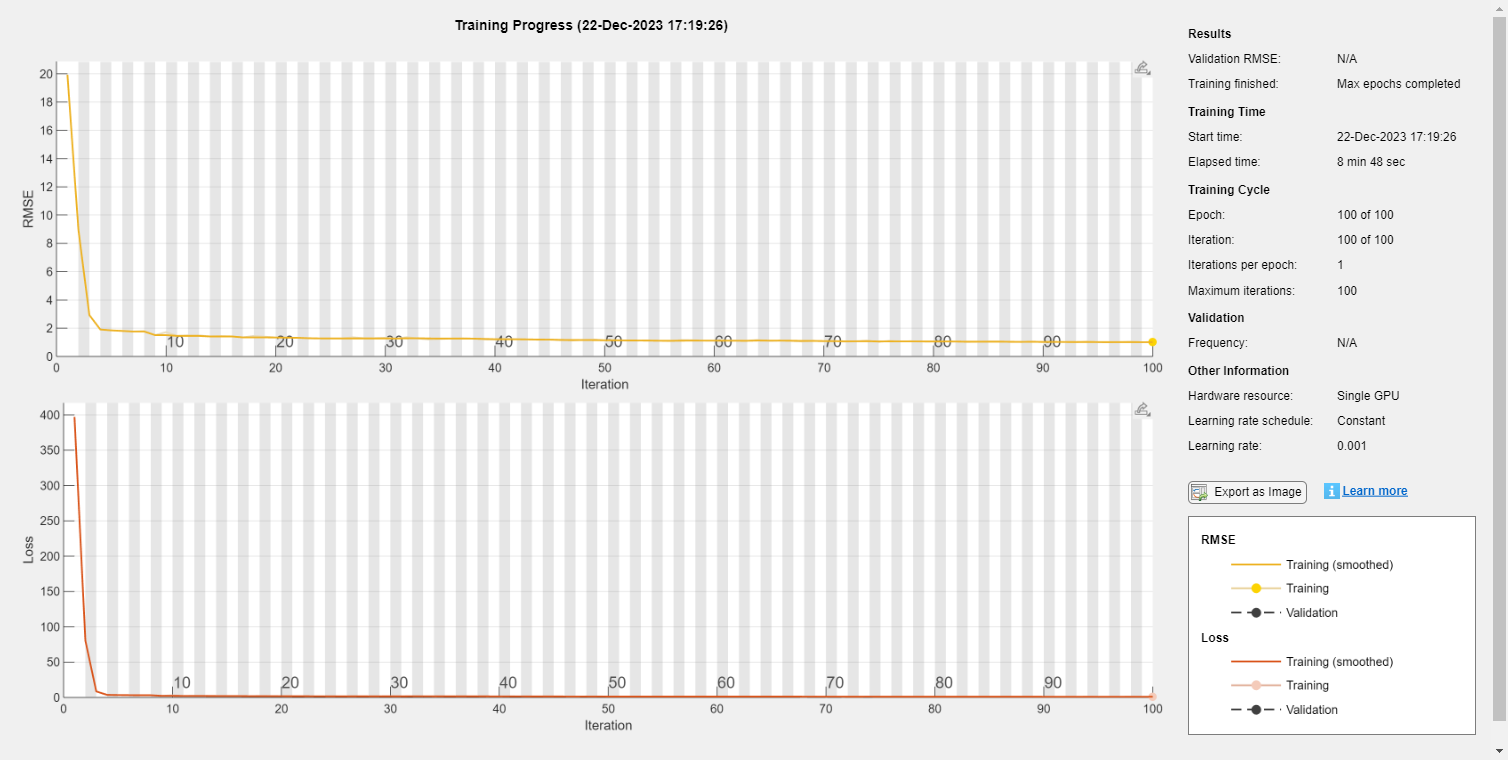

Detector training complete.
*************************************************************************



    [yolov2ConeDetector, info] = trainYOLOv2ObjectDetector(trainingDataSet,lgraph,options);

results = table('Size',[height(testDataSet) 3],...
    'VariableTypes',{'cell','cell','cell'},...
    'VariableNames',{'Boxes','Scores','Labels'});

depVideoPlayer = vision.DeployableVideoPlayer;

for i = 1:height(testDataSet)

    % Read the image
    I = imread(testDataSet.imageFilename{i});

    % Run the detector
    [bboxes,scores,labels] = detect(yolov2ConeDetector,I);

    if ~isempty(bboxes)
        I = insertObjectAnnotation(I,'Rectangle',bboxes,cellstr(labels));
        depVideoPlayer(I);
        pause(0.1);

    end

    % Collect the results in the results table
    results.Boxes{i} = floor(bboxes);
    results.Scores{i} = scores;
    results.Labels{i} = labels;

end
threshold = 0.7;


[ap,recall,precision] = evaluateDetectionPrecision(results, testDataSet(:,2:end),threshold);

[am,fppi,missRate] = evaluateDetectionMissRate(results, testDataSet(:,2:end),threshold);

figure
plot(recall{1,1},precision{1,1},'r-',recall{2,1},precision{2,1},'b:',recall{3,1},precision{3,1},'g-',recall{4,1},precision{4,1},'m-')

Index in position 1 exceeds array bounds. Index must not exceed 2.

hold on;
xlabel('Recall')
ylabel('Precision')
legend('yellow_cone','blue_cone');

figure
loglog(fppi{1,1},missRate{1,1},'r-',fppi{2,1},missRate{2,1},'b:',fppi{3,1},missRate{3,1},'g-',fppi{4,1},missrate{4,1},'m-')
hold on;
xlabel('False Positive Per Image')
ylabel('Log Average Miss Rate')
legend('yellow_cone','blue_cone');